clc;
clear;
format long;

N = 1366 * 1000000 ; % Total Population
I = 184 * 1000; % Total Infected 

B = I;
C = 1027;
D = 82339;
A = N - B - C + D;
disp(A/N);

   0.999924825768668




a = 0.00002;
b = (C/B)/100;
c = D/(100*B);

dAdT = @(x,y,z,X,Y,Z) (-x*X*Y + z*Y);
dBdT = @(x,y,z,X,Y,Z) (x*X*Y - y*Y - z*Y);
dCdT = @(x,y,z,X,Y,Z) (y*Y);
dDdT = @(x,y,z,X,Y,Z) (z*Y);

disp(dDdT(a,b,c,A,B,C));

     8.233900000000000e+02



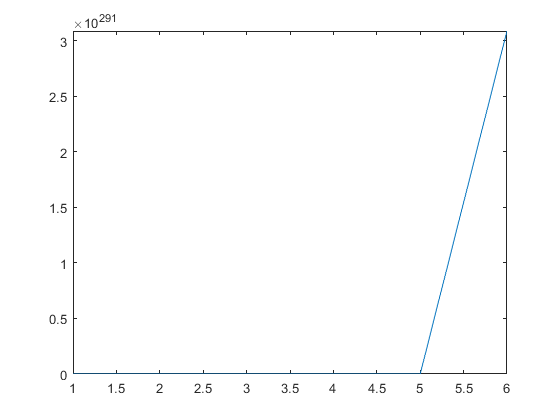


t = 0;
h = 1;
n = 100;
Avalues = A;
Bvalues = B;
Cvalues = C;
Dvalues = D;
nvalues = 1:1:101;
for i = 1:1:n
    Avalues(end+1) = Avalues(end) + h*dAdT(a,b,c,Avalues(end),Bvalues(end),Cvalues(end));
    Bvalues(end+1) = Bvalues(end) + h*dBdT(a,b,c,Avalues(end),Bvalues(end),Cvalues(end));
    Cvalues(end+1) = Cvalues(end) + h*dCdT(a,b,c,Avalues(end),Bvalues(end),Cvalues(end));
    Dvalues(end+1) = Dvalues(end) + h*dDdT(a,b,c,Avalues(end),Bvalues(end),Cvalues(end));
end
Avalues = Avalues/1000000;
plot(nvalues,Bvalues);